**Final Project - Applied Machine Learning (MECH 580)**

**Topic:** Machine learning techniques for house price prediction

**Student:** Yehor Karpichev

# **Background**

People buy and sell houses every day, therefore, a possibility to accurately predict the value of the house is an important and concerning task. The main challenge is to give a fair evaluation taking into consideration a variety of factors – often that includes characteristics like lot area, number of bedrooms, year built, the location, and more. With the developments in AI, it allows to leverage machine learning techniques to overcome complex computations and gain better accuracy [1]. Furthermore the use of ML opens possibilities for things like feature engineering, which allows to better indentify the features that are most relevant, interpreting the relationships between data, and even create new features.

All in all, machine learning may be divided into supervised, unsupervised, and reinforcement learning. Predicting housing prices falls into a supervised learning category. Furthermore, since we are trying to predict a continuous variable (the price), it is a regression task. In comparison to classification, in regression the target variable is continuous: there are no classes, and in fact the output is unbounded. 

Well known regression techniques [2] include but not limited to:

- Linear regression

- Ridge regression

- Lasso regression

- Artificial neural networks

- Decision trees

- Random Forest 

- Support vector machine

- K-nearest neighbor

At the same time, speaking of regression it is crucial to define how the accuracy can be measured. As mentioned before, it is not classification, so the term "accuracy" in its usual sense cannot be used. Instead in regression we measure to what extent our model made a wrong predicition. This can be accoplished by using one of the following estimators: 

- Mean Squared Error (MSE)

- Mean Absolute Error (MAE)

- Root Mean Squared Error (RMSE)

- Mean Absolute Percentage Error (MAPE)

- Mean Squared Logarithmic Error (MSLE)

- R-squared (R2)

For example, MSE is one of the most popular estimators when it comes to regression. It measures the average squares of the error between actual and predicted values. MSE is used as a primary estimator throughout this project.

# **Boston Dataset Loading**

Boston Housing dataset is from 1978, and it's widely used for machine-learning and statistics. The dataset contains 13 features in total, and the goal is to predict housing price.

The dataset can be downloaded from Kaggle platform in .csv format: [https://www.kaggle.com/datasets/arunjangir245/boston-housing-dataset](https://www.kaggle.com/datasets/arunjangir245/boston-housing-dataset)

More information on the dataset can also be found on UToronto website: [https://www.cs.toronto.edu/~delve/data/boston/bostonDetail.html#:~:text=The%20Boston%20Housing%20Dataset,the%20area%20of%20Boston%20Mass](https://www.cs.toronto.edu/~delve/data/boston/bostonDetail.html#:~:text=The%20Boston%20Housing%20Dataset,the%20area%20of%20Boston%20Mass)

*Some related information on the dataset, such as its shortcomings, is discussed further in the Analysis section. 

The Dataset contains the following categories:

- CRIM - per capita crime rate by town

- ZN - proportion of residential land zoned for lots over 25,000 sq.ft.

- INDUS - proportion of non-retail business acres per town.

- CHAS - Charles River dummy variable (1 if tract bounds river; 0 otherwise)

- NOX - nitric oxides concentration (parts per 10 million)

- RM - average number of rooms per dwelling

- AGE - proportion of owner-occupied units built prior to 1940

- DIS - weighted distances to five Boston employment centres

- RAD - index of accessibility to radial highways

- TAX - full-value property-tax rate per $10,000

- PTRATIO - pupil-teacher ratio by town

- B - 1000(Bk - 0.63)^2 where Bk is the proportion of blacks by town

- LSTAT - % lower status of the population

- MEDV - Median value of owner-occupied homes in $1000's  [ *<--- the target variable* ]

% reading the data from the .csv file
housing = readtable('BostonHousing.csv');

# **Getting to know the data**

The goal in this section is to explore the dataset, its features, and distributions.

## Missing values 

Note: in case of Boston dataset - it is known that it has some missing values. Therefore, before proceeding we check for missing values and deal with them. 

The impact of missing values is different for different models. For example, Random Forest is capable of handling this kind of cases, however, in case of linear regression - it may not be able to calculate MSE, and will just output NaN. 

% Check for missing values in the dataset
missing_values = any(ismissing(housing), 1);

% Display the variables with missing values
variables_with_missing = housing.Properties.VariableNames(missing_values);

% Display the number of missing values for each variable
num_missing = sum(ismissing(housing(:, variables_with_missing)));

disp('Variables with missing values:');
disp(variables_with_missing);
disp('Number of missing values for each variable:');
disp(num_missing)

**Dealing with missing values**

In general, in matlab there is a function that can deal with this kind of problems - "fillmissing". It contains multiple methods for dealing with missing data points. In case of Boston dataset, as it is evident from the seciton above, there are in total of only 5 numbers missing, so it would be hard to estimate the effect of different methods on the model's overall performance.

More information on the mentioned function can be found here: [https://www.mathworks.com/help/matlab/ref/fillmissing.html](https://www.mathworks.com/help/matlab/ref/fillmissing.html)

The function provides an option to use several different methods. In our case, the missing values come form the "rm" feature, which stands for the mean number of rooms in the house. So, based on our dataset, the two probably most logical options would be to use "mean" or "knn". 

To resolve this issue, the KNN method is applied, as shown below:

rm_column = housing.rm; % Extract the 'rm' column (which has missing values)

rm_imputed = fillmissing(rm_column, 'knn'); % Assign missing values in the 'rm' column

housing.rm = rm_imputed; % Replace the original 'rm' column with the updated values

Now, let's run again the algorithm for checking if there are any values missing.

% RUN THE CHECK FOR MISSING VALUES AGAIN

Variables with missing values:


    {'rm'}



missing_values = any(ismissing(housing), 1);

Number of missing values for each variable:


vars_with_missing = housing.Properties.VariableNames(missing_values);

     5



num_missing = sum(ismissing(housing(:, vars_with_missing)));
disp('Variables with missing values:');
disp(vars_with_missing);
disp('Number of missing values for each variable:');
disp(num_missing)

As it is seen from the displayed text above, there are no missing values in the dataset anymore.

## Correlation Matrix

Let's compute and visualize the correlation matrix in the format of heatmap. This helps to understand the correlation between different features.

The correlation can be positive or negative. For example, it is positive if both values are increasing, and it is negative when one value increases while the other one decreases.

% Compute the correlation matrix
correlation_matrix = corr(housing{:,:});

figure;
imagesc(correlation_matrix);
colorbar;
colormap('turbo'); 
xticks(1:size(correlation_matrix, 1));
yticks(1:size(correlation_matrix, 1)); 
xticklabels(housing.Properties.VariableNames); 
yticklabels(housing.Properties.VariableNames);  
title('Correlation Matrix of Housing Dataset');
xlabel('Features');
ylabel('Features');

Based on the displayed matrix, several conclusion can be made:

1) CHAS feature doesn't have any particular correlation with any other feature.

CHAS feature represents the dummy variable for Charles river (in Boston), where it's equal to 1 if area bounds river; and it's 0 otherwise.

2) MEDV is the value that we want to predict. From the matrix, we see that the "RM" feature has the most positive correlation with it. The RM feature represents the average number of rooms per dwelling.

## Data distribution

In the following code the historgram for each feature is generated.

numerical_variables = housing{:, :};

Variables with missing values:


num_numerical_variables = size(housing{:,:}, 2); % in case of Boston dataset - 14 variables


Number of missing values for each variable:


num_bins = 10;

% Creating histograms for each variable
figure;
for i = 1:num_numerical_variables
    subplot(ceil(sqrt(num_numerical_variables)), ceil(sqrt(num_numerical_variables)), i);
    histogram(numerical_variables(:, i), num_bins);
    title(housing.Properties.VariableNames{i});
    xlabel('Value');
    ylabel('Frequency');
end

# **Data pre-processing**

Pre-processing  or "normalizing" the data is essencial for training. There are several ways to do it in matlab, which are investigated below. 

But, first of all, let's define our X and Y (in other words, features and target variables)

% Features
inputNames = {'crim','zn','indus','chas','nox','rm','age','dis','rad','tax','ptratio','b','lstat'};

% Target variables
outputNames = {'medv'};

housingAttributes = [inputNames,outputNames];

X = housing{:,inputNames};
Y = housing{:,outputNames};

The "normalize" function in matlab returns the vectorwise z-score of the data in our array with center 0 and standard deviation 1. *z*-scores measure the distance of a data point from the mean in terms of the standard deviation [3].

In the "Results" section the results from raw and zero-to-one normalized data are reported.

The two cells below are not necessary to run - execute it only if you want normalized data for the future use.

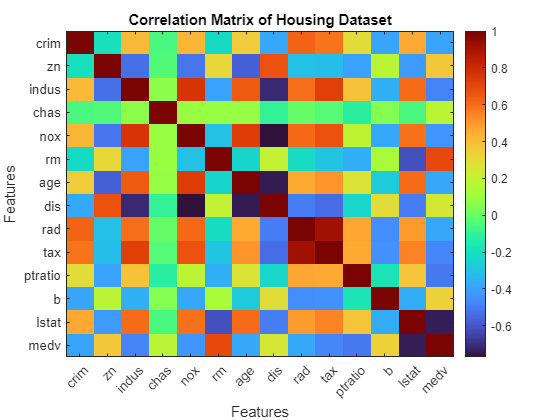

% Option 1

X_norm_1 = normalize(X);
%X = X_norm_1;

% Option 2 - rescales in range [0, 1] 
X_norm_2 = normalize(X, "range");
%X = X_norm_2;

# **Train-Test Split**

Train-test split is intended in order to partition our data for training, validation, and testing.

- Training set is used for traning purpose only

- Validation set is used to validate trainined model, and then implement required changes as judged necessary.

- Test set is used for testing purposes. It is the unseen data for the model. The test set is used only after all models' fine-tuning is finished.

70% of data is reserved for training purpose. While the rest of data is equally distributed for validation and testing (i.e., both 15% from the original dataset).

% Define the ratio for splitting the data
trainRatio = 0.7;  % 70% of data for training
valRatio = 0.15;    % 15% of data for validation
testRatio = 0.15;   % 15% of data for testing

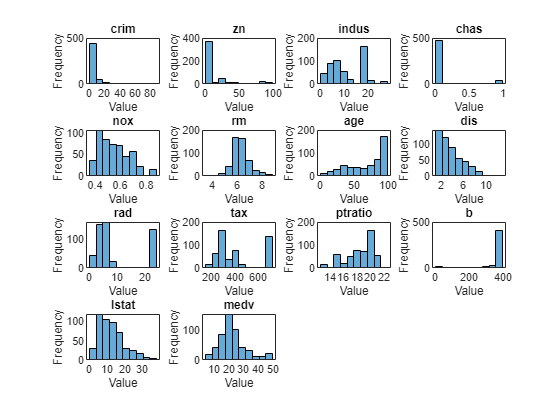

% Calculate the number of samples for each set
numSamples = size(X, 1);

numTrain = floor(trainRatio * numSamples);
numVal = floor(valRatio * numSamples);
numTest = numSamples - numTrain - numVal;

% add a seed to minize randomness
rng(10)

% Create a random partition for the data
c = cvpartition(numSamples, 'HoldOut', 1 - trainRatio);
trainIdx = training(c);  % Indices for training set
tempIdx = find(~trainIdx);  % Indices for validation and testing set
c = cvpartition(length(tempIdx), 'HoldOut', valRatio / (valRatio + testRatio));
valIdx = tempIdx(training(c));  % Indices for validation set
testIdx = tempIdx(test(c));  % Indices for testing set

% Split the data based on the indices
X_train = X(trainIdx, :);
Y_train = Y(trainIdx);
X_val = X(valIdx, :);
Y_val = Y(valIdx);
X_test = X(testIdx, :);
Y_test = Y(testIdx);

Display the sizes of each set:

disp(['Training set size: ', 'X_train = ', num2str(size(X_train)), ', ', 'Y_train = ', num2str(size(Y_train))]);
disp(['Validation set size: ', 'X_val = ', num2str(size(X_val)), ', ', 'Y_val = ', num2str(size(Y_val))]);
disp(['Testing set size: ', 'X_test = ', num2str(size(X_test)), ', ', 'Y_test = ', num2str(size(Y_test))]);

# **Methods**

In this section, the follwoing models are investigated:

- Linear Regression

- Support Vector Regression

- Gradient Boosting Regression

- Regression Trees

- Random Forest Regression

- LSBoost

- 1D CNN

- Neural Networks

All models are trainined and validated using training and validation sets respectively. In the next section, Testing, the final classifiers are evaluated on the test set to compare their performances.

## Regression Trees

A version of decision trees designated for regression tasks.

rng(42);

tree_model = fitrtree(X_train, Y_train); % fit the model
view(tree_model,Mode="graph"); % view the decision process as a graph
% Predicting on the validation set
Y_pred_reg_trees = predict(tree_model, X_val);

% Calculate the mean squared error (MSE)
MSE = mean((Y_val - Y_pred_reg_trees).^2);
disp(['Mean Squared Error (MSE) on Validation Set: ', num2str(MSE)])

### Pruning

Prunning is well-known technique when it comes to the model such as Decision Trees. It is usually utilized in order to improve model's generalization and prevent overfitting. But it also improves computational efficiency and reduces the overall model's complexity. 

In this particular example, for the pruning purposes "alpha" factor (cost) is utilized. It is a scalar in the range from 0 to 1. In case, it is zero - it means no pruning. If it's equal to one -  it leads to prunning to one node as noted on the official matlab documentation: [https://www.mathworks.com/help/stats/regressiontree.prune.html](https://www.mathworks.com/help/stats/regressiontree.prune.html)

rng(42);

% Pruning
alpha = 0.5; % must be between 0 and 1

tree_model_pruned = prune(tree_model, Alpha=alpha);
view(tree_model_pruned,Mode="graph");
% Predicting on the validation set
Y_pred_reg_trees_pruned = predict(tree_model_pruned, X_val);

% Calculate the mean squared error (MSE)
MSE = mean((Y_val - Y_pred_reg_trees_pruned).^2);
disp(['Mean Squared Error (MSE) on Validation Set: ', num2str(MSE)])

First of all, we see rather significant improvement on the validation set, and the generated graph for splits is much cleaner for the pruned version.

The table below shows the difference in model's performance in terms of MSE as the value of alpha varies:

*Tests conducted on the non-normalized data.

Interestingly, the decision tree doesn't change for the alpha values from 0.7 to 0.9 inclusive (with step 0.1).

The best outcome on the validation set was achieved with alpha = 0.5.

## Random Forest Regression

The Random Forest can be considered as classic machine learning technique that nowadays is often underestimated. 

rng(42);

% Define the parameters for the random forest
numTrees = 130;  % Number of trees in the forest

% Training the random forest regression model
rf_model = TreeBagger(numTrees, X_train, Y_train, Method="regression");

Training set size: X_train = 355   13, Y_train = 355    1


Validation set size: X_val = 76  13, Y_val = 76   1


% Predict on validation set

Testing set size: X_test = 75  13, Y_test = 75   1


Y_val_pred_rf = predict(rf_model, X_val);

% Calculate the mean squared error (MSE) on validation set
MSE_val_rf = mean((Y_val - Y_val_pred_rf).^2);

% Display the mean squared error on validation set
disp(['Mean Squared Error (MSE) on Validation Set (Random Forest): ', num2str(MSE_val_rf)]);

Due to the nature of random forest, every time we re-train the model we get different MSE for the same parameters. Therefore, in the code section above the seed is set for running this experiment to minize randomness.

So, as the number of trees in the forest was varied, the following results were obtained. *Tests are condcuted on the non-normalized data:

Random Forest, as expected, has shown quite good results. Nonetheless, I believe due to the specifics of the given dataset, the change in forest size had little to no impact on the calculated MSE.

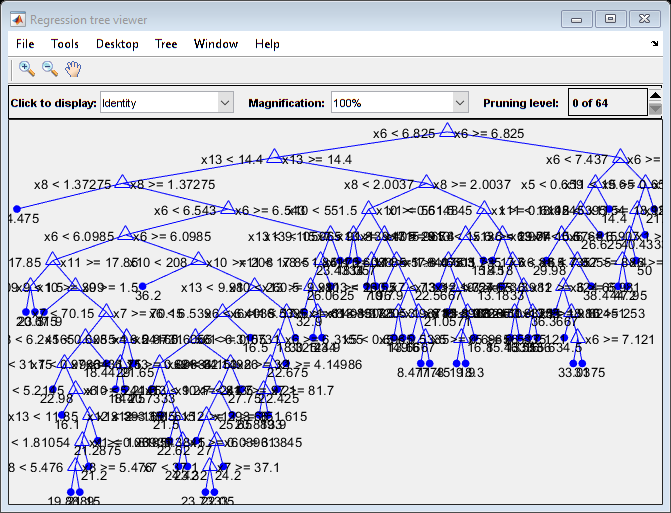

% Plot actual vs. predicted values
figure;
scatter(Y_val, Y_val_pred_rf, 'filled');
hold on;
plot([min(Y_val), max(Y_val)], [min(Y_val), max(Y_val)], 'r--'); % Plotting the line y = x for reference

hold off;
xlabel('Actual Values');
ylabel('Predicted Values');
title('Actual vs. Predicted Values (Validation Set) - Random Forest');
legend('Predicted vs. Actual', 'y = x', 'Location', 'northwest');
grid on;

Mean Squared Error (MSE) on Validation Set: 18.6765


## LSBoost

LSBoost - Least-Squares Boosting is an ensemble technique that combines the principles of boosting with the optimization of a least squares loss function. And it is primarily used for the regression tasks [4].

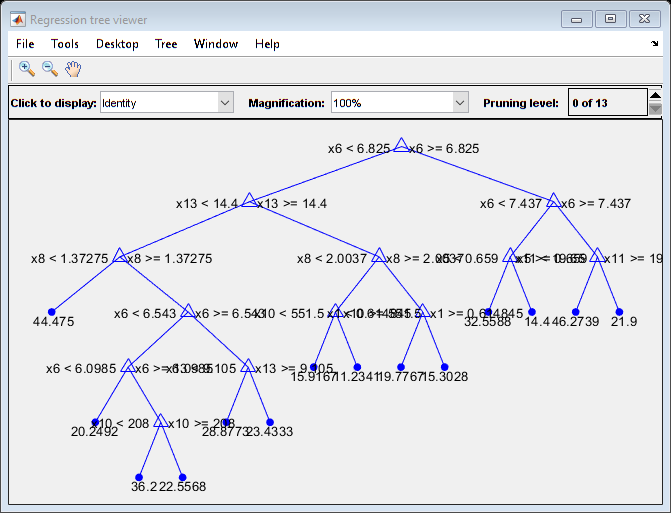

rng(42);

iterations = 500;
lr = 0.01;

lsboost_1 = fitensemble(X_train,Y_train,'LSBoost', iterations, 'Tree', 'LearnRate', lr);
L = loss(lsboost_1,X_val, Y_val,'mode','ensemble');

fprintf('Mean-square validation error = %f\n',L);

However, for this specific model we can follow the provided example by Matlab - we can also implement additional parameters into the model to try to boost its performance.

Original matlab tutorial: [https://www.mathworks.com/products/demos/machine-learning/boosted-regression.html](https://www.mathworks.com/products/demos/machine-learning/boosted-regression.html)

rng(42);

t = RegressionTree.template('MinLeaf',5);
lsboost_2 = fitensemble(X_train,Y_train,'LSBoost', iterations, t, 'LearnRate', lr);
L = loss(lsboost_2,X_val, Y_val,'mode','ensemble');

Mean Squared Error (MSE) on Validation Set: 14.7848


fprintf('Mean-square validation error = %f\n',L);

As we can see from the calculated MSEs, after we integrated the minimum leaf size the model's error is reduced more than in two times.

## Linear Regression

Linear regression is one of the fundamental statistical methods used for modeling the relationship between a dependent variable (i.e. target) and independent variables (i.e. features). It operates under the assumption that the relationship between the variables is linear, meaning that changes in the independent variables result in proportional changes in the dependent variable.

In the context of machine learning, we can see linear regression as basis for more complex models and algorithms.

rng(42);

% Perform linear regression
linear_regression_model = fitlm(X_train, Y_train);

% Predict on validation set
Y_val_pred_linear_regression = predict(linear_regression_model, X_val);

% Calculate the mean squared error (MSE) on validation set
MSE_val_linear_regression = mean((Y_val - Y_val_pred_linear_regression).^2);

% Display the mean squared error on validation set
fprintf('Mean-square validation error = %f\n',MSE_val_linear_regression);

% Plot actual vs. predicted values
figure;

Mean Squared Error (MSE) on Validation Set (Random Forest): 11.6345


scatter(Y_val, Y_val_pred_linear_regression, 'filled');
hold on;
plot([min(Y_val), max(Y_val)], [min(Y_val), max(Y_val)], 'r--'); % Plotting the line y = x for reference
hold off;
xlabel('Actual Values');
ylabel('Predicted Values');
title('Actual vs. Predicted Values (Validation Set) - Linear Regression');
legend('Predicted vs. Actual', 'y = x', 'Location', 'northwest');
grid on;

Based on the generated graph, it is really interesting to see that for one of the data points, linear regression managed to predict a negative value. This is specifics of the regression problem - the output doesn't have any specific bounds. For example, in classification the output is usually limited to only provided (or possible) classes.

## Support Vector Regression

Support Vector Machine (SVM) is a machine learning algorithm that aims to find the optimal hyperplane (also referred to as decision boundary) that best separates the data points while maximizing the margin between the points and the hyperplane [5].

In case of regression, SVM aims to minimize the difference between predicted and real values. It is capable of handling both linear and non-llinear reshipships thanks to the various kernel functions. Two SVM models are fit below using linear and radial basis function kernels.  

Linear:

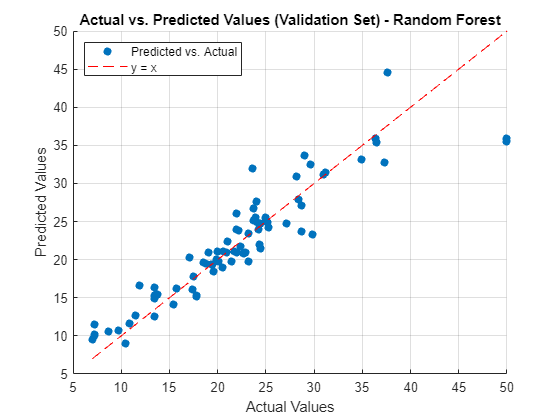

%rng(42);

% Train the SVM regression model
svm_model_linear = fitrsvm(X_train, Y_train, 'KernelFunction', 'linear');

% Make predictions on the test set
Y_pred_svm_linear = predict(svm_model_linear, X_val);


% Calculate the mean squared error (MSE)
MSE = mean((Y_val - Y_pred_svm_linear).^2);
disp(['Mean Squared Error (MSE) on Validation Set: ', num2str(MSE)]);
% Plot actual vs. predicted values
figure;
scatter(Y_val, Y_pred_svm_linear, 'filled');
hold on;
plot([min(Y_val), max(Y_val)], [min(Y_val), max(Y_val)], 'r--');
hold off;
xlabel('Actual Values');
ylabel('Predicted Values');
title('Actual vs. Predicted Values (Validation Set) - SVM linear');

Mean-square validation error = 19.194299


legend('Predicted vs. Actual', 'y = x', 'Location', 'northwest');
grid on;

It is interesting to compare the graph generated with Linear Regression and linear SVM. The MSE between the models is very similar, and we can see which points are misclassified.

Gaussian:

%rng(42);

svm_model_rbf = fitrsvm(X_train, Y_train, 'KernelFunction', 'gaussian');

% Make predictions on the test set
Y_pred_svm_rbf = predict(svm_model_rbf, X_val);

% Calculate the mean squared error (MSE)

Mean-square validation error = 8.873131


MSE = mean((Y_val - Y_pred_svm_rbf).^2);
disp(['Mean Squared Error (MSE) on Validation Set: ', num2str(MSE)]);

## K-NN

K-Nearest Neighbors (K-NN) is quite simple algorithm used for both classification and regression tasks. In the context of this project, i.e. for regression purpose, K-NN computes the average of the target values of the K nearest neighbors and assigns this average value as the predicted target value for the new data point [6].

rng(42);

% Train the K-NN model
k = 2; % Number of nearest neighbors
knn_model = fitcknn(X_train, Y_train, 'NumNeighbors', k);

% Make predictions on the test set
Y_pred_knn = predict(knn_model, X_val);

% Calculate the mean squared error (MSE)
MSE = mean((Y_val - Y_pred_knn).^2);

disp(['Mean Squared Error (MSE) on Validation Set: ', num2str(MSE)]);

Mean-square validation error = 20.510611


*Tests conducted on the non-normalized data

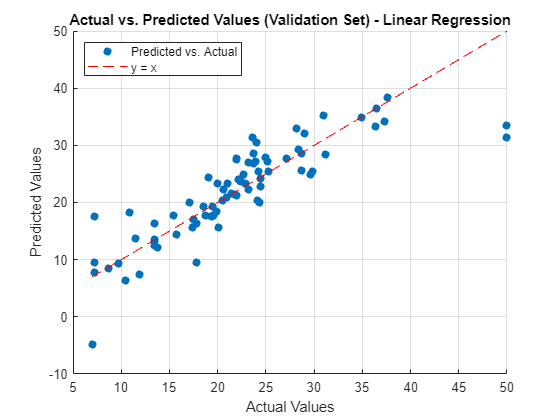

% Plot actual vs. predicted values
figure;
scatter(Y_val, Y_pred_knn, 'filled');
hold on;
plot([min(Y_val), max(Y_val)], [min(Y_val), max(Y_val)], 'r--');
hold off;
xlabel('Actual Values');
ylabel('Predicted Values');
title('Actual vs. Predicted Values (Validation Set) - K-NN');
legend('Predicted vs. Actual', 'y = x', 'Location', 'northwest');
grid on;

## 1D CNN

Typically 1D CNN deals with sequantial or temporal data. Overall, it may be not the best choice for house prediction regression problem since our dataset is not time-series. 

As evident from the code below, some data transformation is needed to make it suitable for the model's input - another dimension is artificially added, and in fact it cannot be properly used by the model for prediction estimations. 

rng(42);

% Prepare the data
X_train_expanded = reshape(X_train, [13 1 355]);
Y_train_expanded = reshape(Y_train, [1 355]);

X_val_expanded = reshape(X_val, [13 1 76]);
Y_val_expanded = reshape(Y_val, [1 76]);

X_test_expanded = reshape(X_test, [13 1 75]);
Y_test_expanded = reshape(Y_test, [1 75]);

% Define the architecture of our 1D CNN model
layers1D_CNN = [
    sequenceInputLayer([13 1])
    convolution1dLayer(3, 16, 'Padding', 'same')
    reluLayer

Mean Squared Error (MSE) on Validation Set: 24.2518


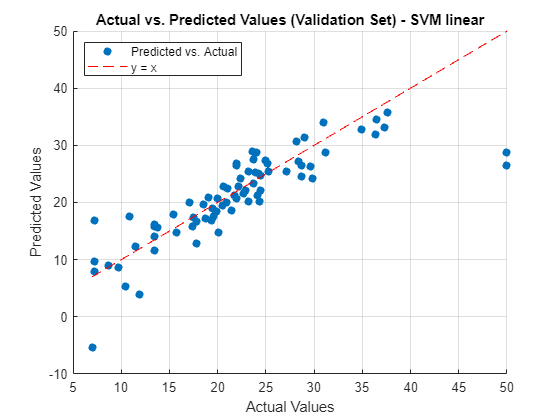

    maxPooling1dLayer(2, 'Stride', 2, 'Padding', 'same')
    convolution1dLayer(3, 32, 'Padding', 'same') 
    reluLayer
    maxPooling1dLayer(2, 'Stride', 2, 'Padding', 'same')
    flattenLayer
    fullyConnectedLayer(50)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(1)

    regressionLayer 
];

lgraph1DCNN = layerGraph(layers1D_CNN);
plot(lgraph1DCNN)
% Specifying training options
options_1D_CNN = trainingOptions('adam', ... 
    'MaxEpochs', 300, ... 
    'MiniBatchSize', 64, ... 
    'InitialLearnRate', 0.01, ... 
    'Shuffle', 'every-epoch', ... 
    'ValidationData', {X_val_expanded, Y_val_expanded}, ... 
    'ValidationFrequency', 10, ... 

Mean Squared Error (MSE) on Validation Set: 71.4313


    'Verbose', false, ...
    'Plots', 'training-progress');


% Train the 1D CNN model
net_1D_CNN = trainNetwork(X_train_expanded, Y_train_expanded, layers1D_CNN, options_1D_CNN);

% Make predictions on the validation data:
Y_val_pred_1D_CNN = predict(net_1D_CNN, X_val_expanded);
Y_val_pred_1D_CNN = double(Y_val_pred_1D_CNN);

mse = immse(Y_val_expanded, Y_val_pred_1D_CNN);

fprintf('Mean Squared Error (MSE) on validation data: %.4f\n', mse);

As expected 1D CNN did not perform very well, especially when MSE is compared to other models. 

Interestingly, during training for more epochs the evident signs of overfitting started to manifest - a bigger gap between training and validation, furthermore, the validation accuracy started to become worse. The addition of dropout layer did help, however, some overfitting seems to be happening anyway.

## Neural Networks

The use of deep neural networks is investigated for the regression problem. 

All in all, several variations of the model are tested. For example, in the begining an arbitrary model with 2 FC layers followed by relu activations was chosen (layers_NN_1). 

The 2nd model (layers_NN_2) is practically the same, however, it uses sigmoid activation fucntion instead of relu.

 Meanwhile the 3rd (layers_NN_3) model is the same as 1st but a dropout layer is added for regularization purposes.

For the input layer in all models, the "featureInputLayer" is used as mentioned in documentation: [https://www.mathworks.com/help/deeplearning/ref/trainnet.html](https://www.mathworks.com/help/deeplearning/ref/trainnet.html)

% Define the architecture of the neural network
features = size(X_train, 2); % 13 in case of Boston dataset

% 2 fully connected layers with relu activation

Mean Squared Error (MSE) on Validation Set: 48.1862


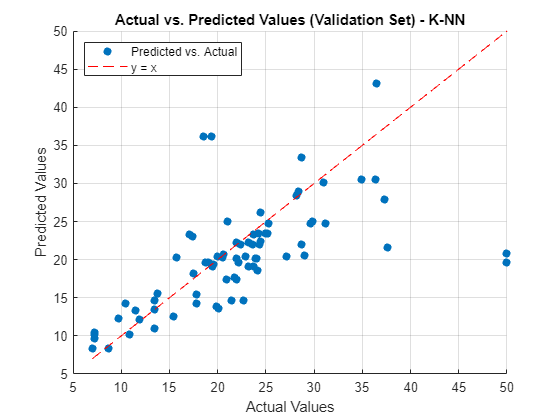

layers_NN_1 = [
    featureInputLayer(features)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer
];

% 2 FC layers with sigmoid activation
layers_NN_2 = [
    featureInputLayer(features)
    fullyConnectedLayer(50)
    sigmoidLayer

    fullyConnectedLayer(30)
    sigmoidLayer
    fullyConnectedLayer(1)
    regressionLayer
];

% 2 FC layers with relu activation and dropout layers
layers_NN_3 = [
    featureInputLayer(features)
    fullyConnectedLayer(50)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer
];

For a better visual compresension, the 3 different above-mentioned modes are imported into the deepNetworkDesigner. From left to right: layers_NN_1, layers_NN_2, layers_NN_3.

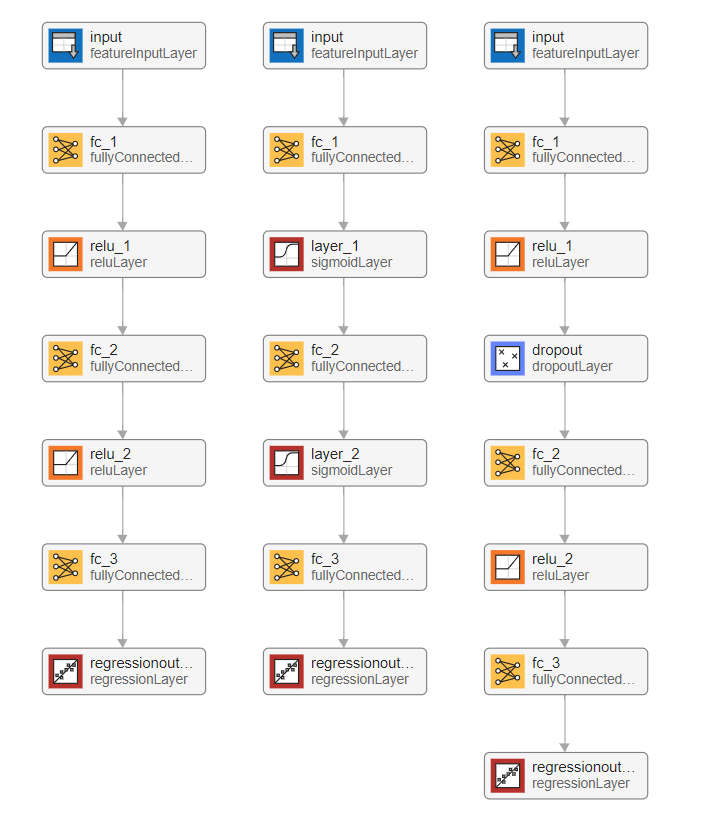

Adam and SGD optimizers are tested. Furthermore, for every trial shown below the training options are slightly modified, for example in terms of maxepochs, mini-batch size or learning rate in an attempt to optimize performance.

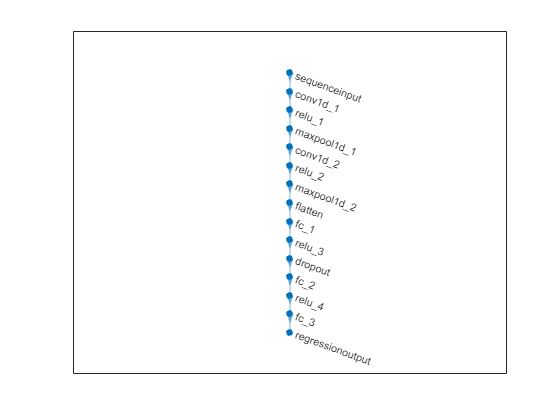

% Specify training options

% SGD optimizer
options_NN_sgd_1 = trainingOptions('sgdm', ... 
    'MaxEpochs', 120, ... 
    'MiniBatchSize', 64, ... 
    'InitialLearnRate', 0.00001, ... 
    'Shuffle', 'every-epoch', ... 
    'ValidationData', {X_val, Y_val}, ... 
    'ValidationFrequency', 10, ... 
    'Verbose', false, ...
    'Plots', 'training-progress');
% One of the big issues for trying to train the model with SGD solver was overcoming the problem of getting NaN loss at the 2nd epoch. 
% Reducing learning rate for SGD helped to avoid this kind of situations. 
% additional information: https://stackoverflow.com/questions/37232782/nan-loss-when-training-regression-network
% It seems like neural networks with SGD are prone to this kind of problems particularly in the regression tasks since the output is unbounded.
% The likely cause of NaN loss is the exploding gradient problem.


% ADAM optimizer
options_NN_adam_1 = trainingOptions('adam', ... 

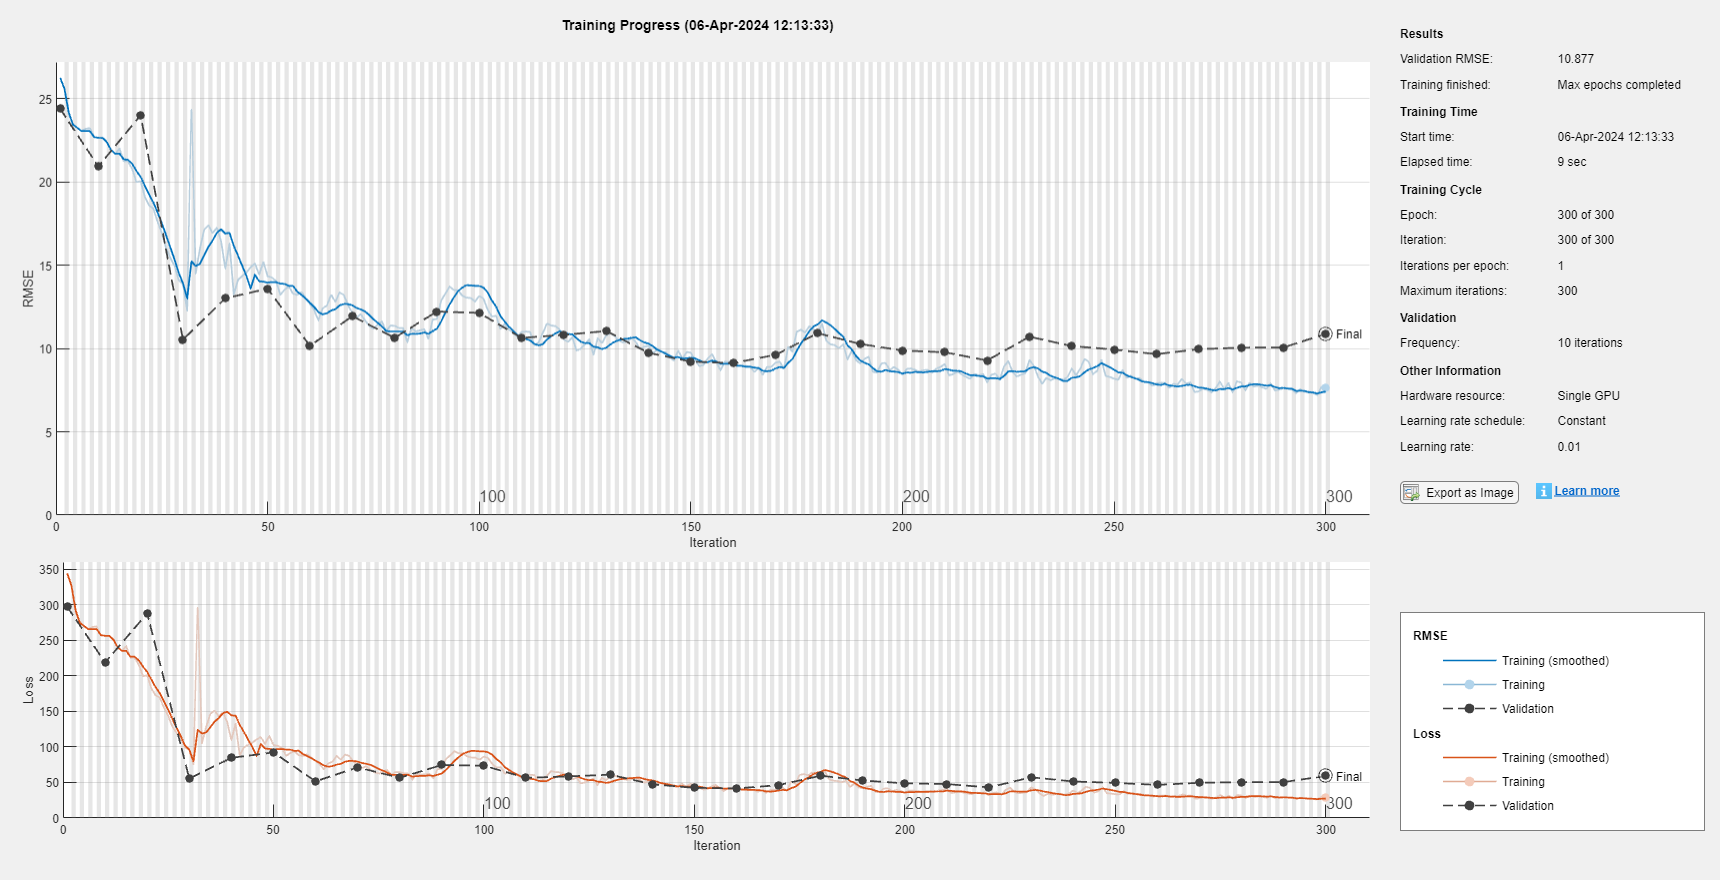

    'MaxEpochs', 100, ... 
    'MiniBatchSize', 32, ... 
    'InitialLearnRate', 0.01, ... 
    'Shuffle', 'every-epoch', ... 
    'ValidationData', {X_val, Y_val}, ... 
    'ValidationFrequency', 10, ... 
    'Verbose', false, ...
    'Plots', 'training-progress');

options_NN_adam_2 = trainingOptions('adam', ... 
    'MaxEpochs', 1000, ... 
    'MiniBatchSize', 64, ... 
    'InitialLearnRate', 0.001, ... 
    'Shuffle', 'every-epoch', ... 

    'ValidationData', {X_val, Y_val}, ... 
    'ValidationFrequency', 20, ... 
    'Verbose', false, ...
    'Plots', 'training-progress');

options_NN_adam_3 = trainingOptions('adam', ... 
    'MaxEpochs', 200, ... 
    'MiniBatchSize', 32, ... 

Mean Squared Error (MSE) on validation data: 118.3065


    'InitialLearnRate', 0.001, ... 
    'Shuffle', 'every-epoch', ... 
    'ValidationData', {X_val, Y_val}, ... 
    'ValidationFrequency', 10, ... 
    'Verbose', false, ...
    'Plots', 'training-progress');

**Training the model with SGD optimizer:**

net_NN_sgd = trainNetwork(X_train, Y_train, layers_NN_1, options_NN_sgd_1);

% Make predictions on the validation data:
Y_val_pred_NN = predict(net_NN_sgd, X_val);
Y_val_pred_NN = double(Y_val_pred_NN);

mse = immse(Y_val, Y_val_pred_NN);

fprintf('Mean Squared Error (MSE) on validation data: %.4f\n', mse);

**Training the model with Adam optimizer:**

- net_NN_adam_1 corresponds to the model with just Adam optimizer and relu activation.

- net_NN_adam_2 corresponds to the same model, but with sigmoid activation functions.

- net_NN_adam_3 has structure and options similar to net_NN_adam_1, but a dropout layer is added.

% original testing of NN with adam optimizer and relu activation
net_NN_adam_1 = trainNetwork(X_train, Y_train, layers_NN_1, options_NN_adam_1);

% Make predictions on the validation data:
Y_val_pred_NN = predict(net_NN_adam_1, X_val);
Y_val_pred_NN = double(Y_val_pred_NN);

mse = immse(Y_val, Y_val_pred_NN);
fprintf('Mean Squared Error (MSE) on validation data: %.4f\n', mse);

% using sigmoid as activation
net_NN_adam_2 = trainNetwork(X_train, Y_train, layers_NN_2, options_NN_adam_2);

% Make predictions on the validation data:
Y_val_pred_NN = predict(net_NN_adam_2, X_val);
Y_val_pred_NN = double(Y_val_pred_NN);

mse = immse(Y_val, Y_val_pred_NN);
fprintf('Mean Squared Error (MSE) on validation data: %.4f\n', mse);

We can see that the 2 experiments with Adam optimizer above showed quite similar MSE. However, in the 2nd test, the MSE was slightly higher, and more important, it took significantly more time for training.

% testing the idea of adding a dropout layer
net_NN_adam_3 = trainNetwork(X_train, Y_train, layers_NN_3, options_NN_adam_3);

% Make predictions on the validation data:
Y_val_pred_NN = predict(net_NN_adam_3, X_val);
Y_val_pred_NN = double(Y_val_pred_NN);

mse = immse(Y_val, Y_val_pred_NN);
fprintf('Mean Squared Error (MSE) on validation data: %.4f\n', mse);

In case of this 3rd experiment (with the model that has dropout layers) - it took quite long time for the model to be trained. Furthermore, I think due to dropout layers, some of the weights are lost, so every time we re-train the model the results may vary quite a lot. For example, after running the training process of this 3rd model, the resulted MSE on the vlaidation set was between 15 to almost 50.

# **Testing**

In this chapter we shall test the trained models on the test set (which is unseen data).

So, I am taking the pre-trained classifiers from the previous chapter, and use the test set to test models' capacity to predict on the previously unseen data.

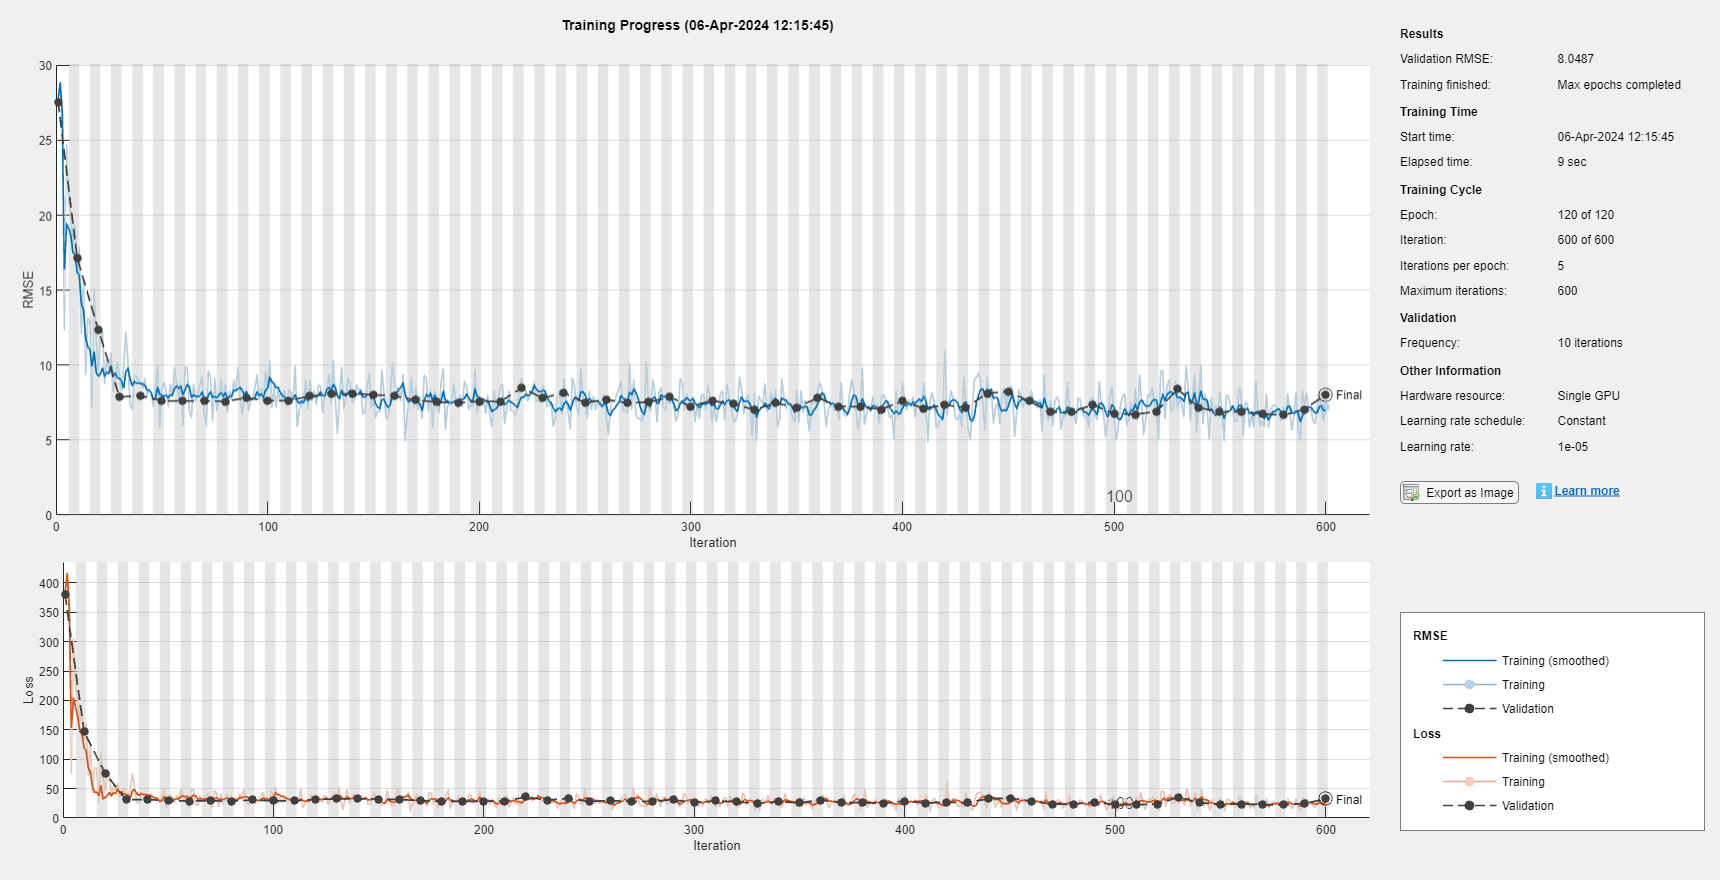

% Regression trees
Y_test_pred_reg_tree = predict(tree_model, X_test);

Y_test_pred_reg_tree = double(Y_test_pred_reg_tree);
mse_reg_tree = immse(Y_test, Y_test_pred_reg_tree);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_reg_tree);
% Regression trees (pruned)
Y_test_pred_reg_tree_pruned = predict(tree_model_pruned, X_test);
Y_test_pred_reg_tree_pruned = double(Y_test_pred_reg_tree_pruned);
mse_reg_tree_pruned = immse(Y_test, Y_test_pred_reg_tree_pruned);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_reg_tree_pruned);

Mean Squared Error (MSE) on validation data: 64.7814


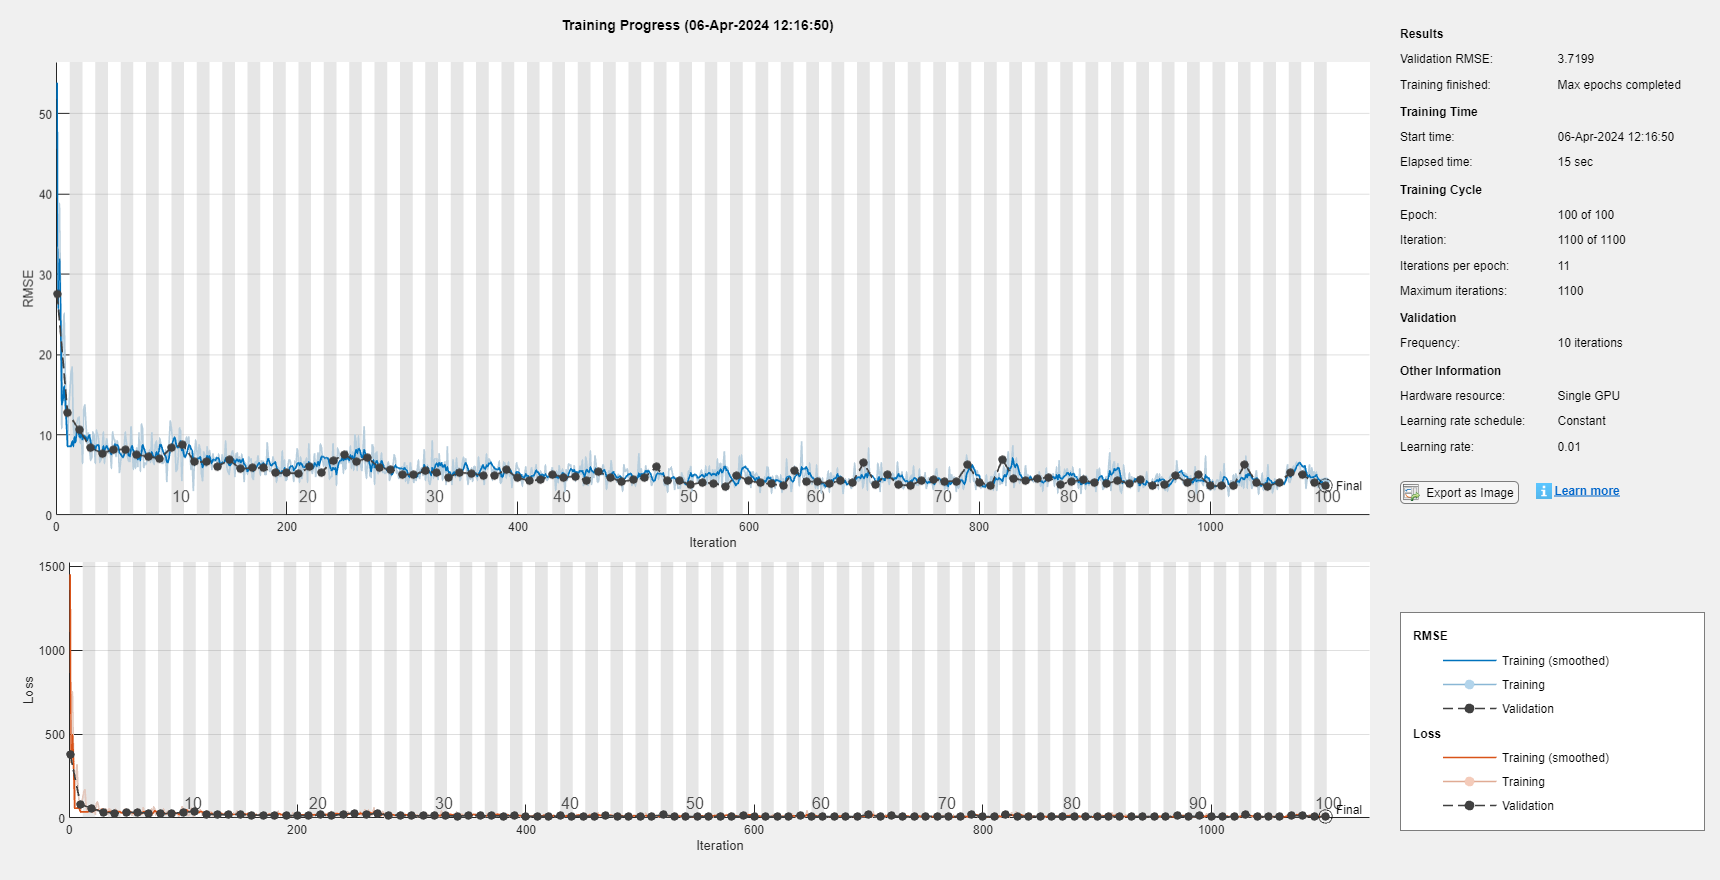

% Random Forest regression
Y_test_pred_rf = predict(rf_model, X_test);
Y_test_pred_rf = double(Y_test_pred_rf);
mse_rf = immse(Y_test, Y_test_pred_rf);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_rf);
% LSBoost

Y_test_pred_lsboost = predict(lsboost_2, X_test);
Y_test_pred_lsboost = double(Y_test_pred_lsboost);
mse_lsboost = immse(Y_test, Y_test_pred_lsboost);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_lsboost);
% Linear regression
Y_test_pred_linear_reg = predict(linear_regression_model, X_test);
Y_test_pred_linear_reg = double(Y_test_pred_linear_reg);

Mean Squared Error (MSE) on validation data: 13.8375


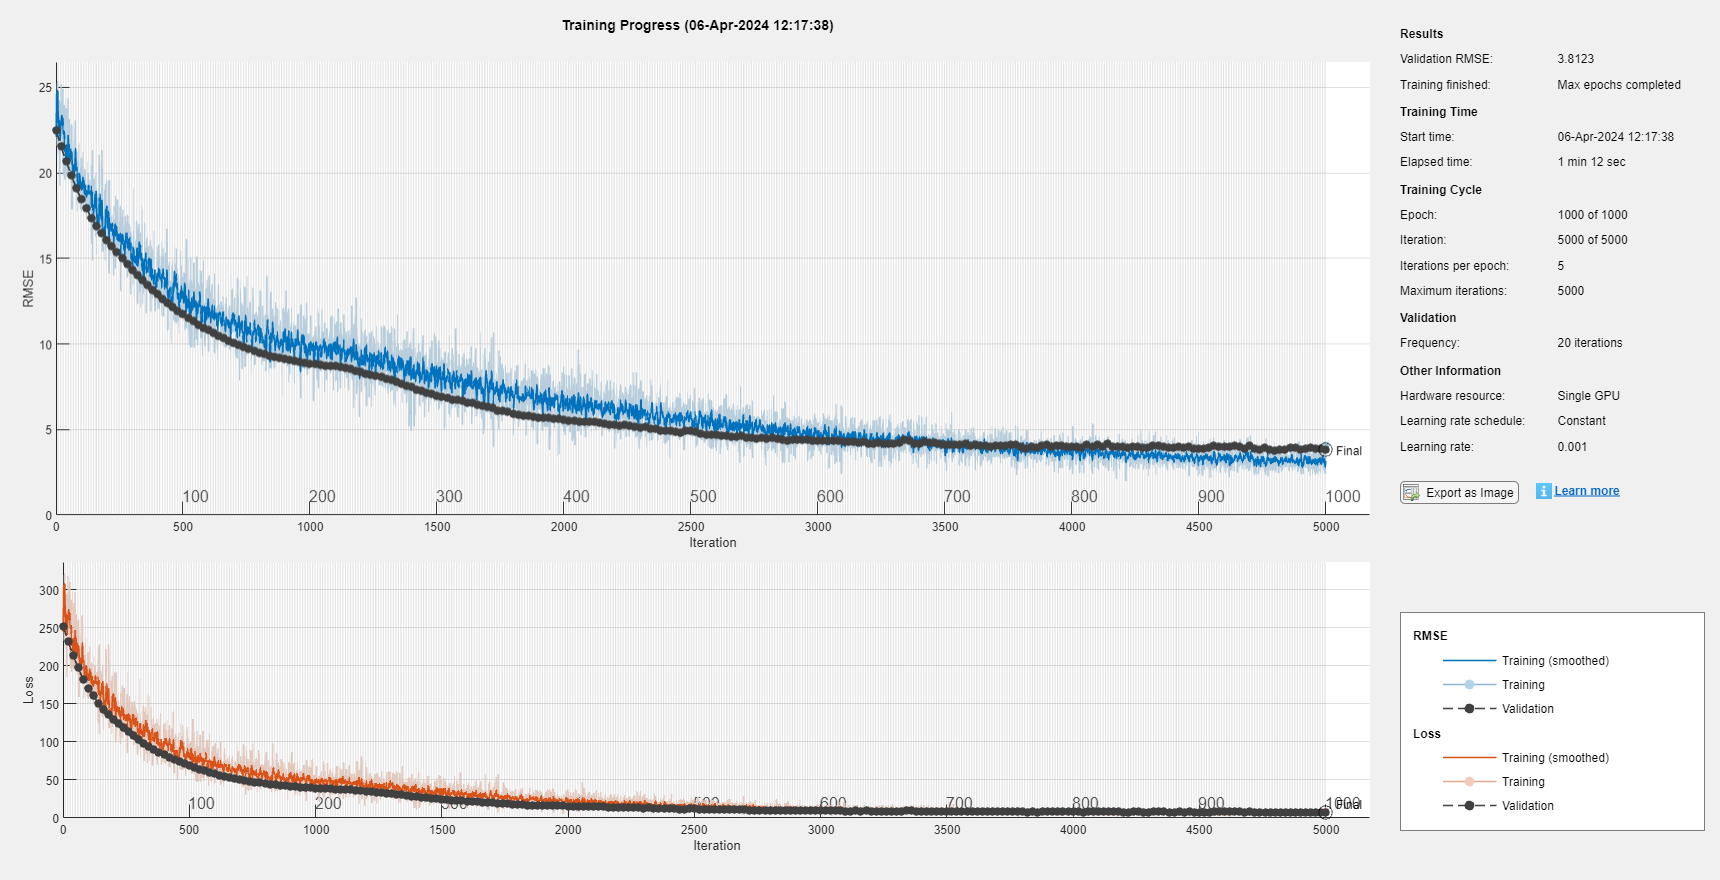

mse_linear_reg = immse(Y_test, Y_test_pred_linear_reg);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_linear_reg);
% K-NN

Y_test_pred_knn = predict(knn_model, X_test);
Y_test_pred_knn = double(Y_test_pred_knn);
mse_knn = immse(Y_test, Y_test_pred_knn);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_knn);
% Support vector machine (linear) regression
Y_test_pred_svm_linear = predict(svm_model_linear, X_test);
Y_test_pred_svm_linear = double(Y_test_pred_svm_linear);

Mean Squared Error (MSE) on validation data: 14.5336


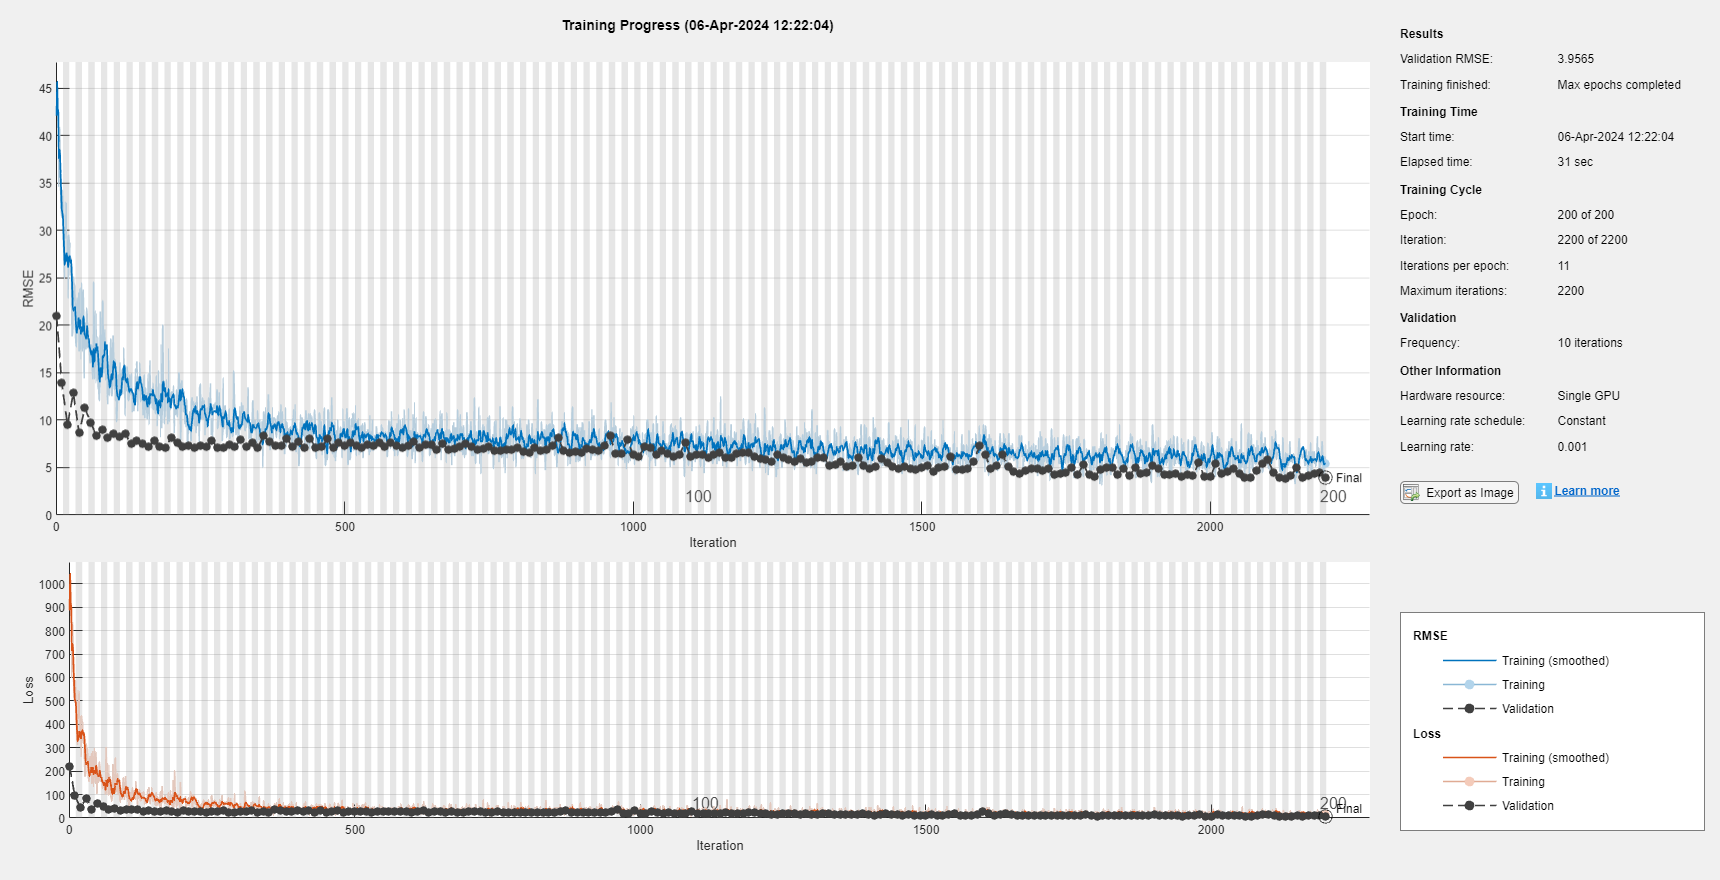

mse_SVM_linear = immse(Y_test, Y_test_pred_svm_linear);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_SVM_linear);
% Support vector machine (rbf) regression
Y_test_pred_svm_rbf = predict(svm_model_rbf, X_test);

Y_test_pred_svm_rbf = double(Y_test_pred_svm_rbf);
mse_SVM_rbf = immse(Y_test, Y_test_pred_svm_rbf);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_SVM_rbf);
% 1D CNN
Y_test_pred_1D_CNN = predict(net_1D_CNN, X_test_expanded);
Y_test_pred_1D_CNN = double(Y_test_pred_1D_CNN);
mse_1D_CNN = immse(Y_test_expanded, Y_test_pred_1D_CNN);

Mean Squared Error (MSE) on validation data: 15.6540


fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_1D_CNN);
% Neural Netowkrs (SGD solver)
Y_test_pred_NN_sgd = predict(net_NN_sgd, X_test);
Y_test_pred_NN_sgd = double(Y_test_pred_NN_sgd);
mse_nn_sgd = immse(Y_test, Y_test_pred_NN_sgd);
fprintf('Mean Squared Error (MSE) on test set: %.4f\n', mse_nn_sgd);
% Neural Networks (Adam solver)
Y_test_pred_NN_adam = predict(net_NN_adam_1, X_test);
Y_test_pred_NN_adam = double(Y_test_pred_NN_adam);
mse_nn_adam = immse(Y_test, Y_test_pred_NN_adam);

Mean Squared Error (MSE) on test set: 13.1521


fprintf('Mean Squared Error (MSE) ontest set: %.4f\n', mse_nn_adam);

# **Final Results**

This section presents a summary of the obtained results in the form of comparison tables, comparing performances of all models from the previous section. Two tables are provided below: one displaying the results obtained using raw data, and the other showing the mean squared errors after normalizing the input data to a range of [0, 1]. Each table has three rows with reported MSE based on: training, validation, and test sets.

**Results with non-normalized data (i.e., raw data): **

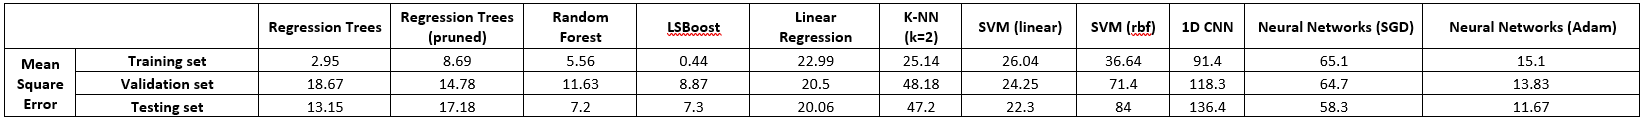

**Results with normalized data:**

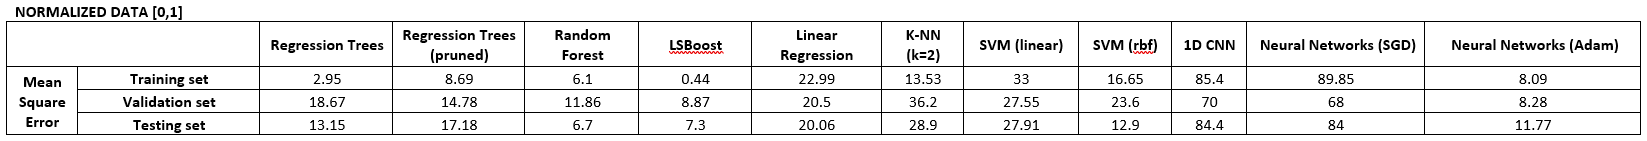

Several conclusions & observations that should be noted:

- Random Forest Rgeresison model outperforms every single other model that was considered as part of this project. Random Forest is a well known model that is robust to overfitting, it has ability to handle missing values and work with outliers, and capture non-linear relationships.

- LSBoost gave also a similar MSE to Random Forest, but still it was slightly higher.

- Pruned Regression trees seem to perform better than fully grown based on the MSE on the validation set. However, on the test set we see an opposite behavior. One possible explanation could be the specifics of the dataset, namely the small dataset size - therefore, the model's performance becomes sensitive to which samples fall into training, validation, and testing sub-sets.

- In terms of neural networks - several networks were trained and tested, eventually the MSE was reported for NN with Adam and SGD optimizers. As expected (based on the previous experience), Adam solver helped achieving a significantly lower error. 

- 1D CNN gave one of the worst performances. However, as mentioned in the respective subsecton, where 1D CNN is trained,  this is not the best model for the task at hand simply because our dataset has no temporal dimension. 

- Normalization of data. As evident from the provided tables, several models managed to get much lower MSE when data was normalized. It affected models such as K-NN, SVMs (especially with rbf kernel), 1D CNN, and Neural Networks. In case of SVM with rbf kernel the change in error is particularly large (84 vs 12.9 on the test set).

# **Principle Component Analysis**

Principal Component Analysis (PCA) is a dimensionality reduction technique widely used in various fields, including data science, machine learning, and signal processing. The idea behind PCA is to transform high-dimensional data into a lower-dimensional representation while preserving the essential information from the original dataset [7]. It's important to note that PCA identifies the directions (principal components) in the feature space that capture the maximum variance in the data.

Ideally, PCA is performed in the beginning of project in order to explore the dataset, and possible reduce the dimension. Furthermore, it is more well-known technique in relation to clustering, classification or signal processing related taks. In case of regression, PCA may assist with dimension & noise reduction, and can be used for feature engineering. 

In the context of this project, the use of PCA in Matlab is explored, together with how it may or may not help classifiers to learn better.

*Please note that PCA section is not directly related to the previous sections - the idea here is to explore the method and its functionality in Matlab.

% Performing normalization of data in range [0,1]
X_standardized = normalize(X, "range");

[~, score, ~, ~, explained] = pca(X_standardized);


Mean Squared Error (MSE) on test set: 17.1812


% Create a scatter plot of the data in the space of the first two principal components
scatter(score(:,1),score(:,2))
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

Mean Squared Error (MSE) on test set: 7.2277


title('Scatter Plot of Data in the Space of the First Two Principal Components');
% Create a scatter plot of the data in the space of the first three principal components
scatter3(score(:,1),score(:,2),score(:,3))
axis equal
xlabel('1st Principal Component')

Mean Squared Error (MSE) on test set: 7.3193


ylabel('2nd Principal Component')
zlabel('3rd Principal Component')

### PCA with LR

In the example below a full dataset is divided into training and testing sets (with 80-20 split). Then, a linear regression model is taken as the basis. The model is fit on normalized data as well as on the transformed data after applying PCA.

% Getting MSE from linear regression as the basis for comparison to PCA-modified data

% Performing normalization of data in range [0,1]

Mean Squared Error (MSE) on test set: 20.0699


X_standardized = normalize(X, "range");

% Split the data into training and testing sets
rng(10); 
cv = cvpartition(size(X_standardized, 1), 'HoldOut', 0.2); % 80% train, 20% test

Mean Squared Error (MSE) on test set: 47.2648


X_train = X_standardized(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X_standardized(test(cv), :);
Y_test = Y(test(cv), :);


Mean Squared Error (MSE) on test set: 22.2893


% Train linear regression model
linear_regression = fitlm(X_train, Y_train);
% Predict on the test set
Y_pred_lr = predict(linear_regression, X_test);
% Evaluate the model

Mean Squared Error (MSE) on test set: 83.9233


mse_lr = immse(Y_test, Y_pred_lr); % Mean Squared Error
% Display evaluation metrics
fprintf('Mean Squared Error (MSE): %.4f\n', mse_lr);

% Performing normalization of data in range [0,1]
X_standardized = normalize(X, "range");

Mean Squared Error (MSE) on test set: 136.4168



[coeff, score, latent] = pca(X_standardized);

num_components = 10;


Mean Squared Error (MSE) on test set: 58.3453


% Keep only the selected principal components
X_pca = score(:, 1:num_components);

% Split the data into training and testing sets
rng(10); 

Mean Squared Error (MSE) ontest set: 11.6754


cv = cvpartition(size(X_pca, 1), 'HoldOut', 0.2); % 80% train, 20% test
X_train = X_pca(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X_pca(test(cv), :);
Y_test = Y(test(cv), :);

% Train linear regression model
linear_regression_pca = fitlm(X_train, Y_train);
% Predict on the test set
Y_pred_lr_pca = predict(linear_regression_pca, X_test);
% Evaluate the model
mse_lr_pca = immse(Y_test, Y_pred_lr_pca); % Mean Squared Error
% Display evaluation metrics
fprintf('Mean Squared Error (MSE) after PCA: %.4f\n', mse_lr_pca);

Comparison table for LR MSE using data after PCA with varied number of principle components:

Based on the calculated MSE (seen in the table above), we may conclude that using less number of principle components doesn't help, and even vice versa - it gives a significantly higher MSE.

However, we may notice a minor decrease in error as number of PCs is reduced from 13 to 10. I believe this improvement in MSE might be explained by the removal of noise in data thanks to PCA transformation.

### PCA with NN 

Now, let's try to test the impact of using different number of PCs for fitting neural networks:

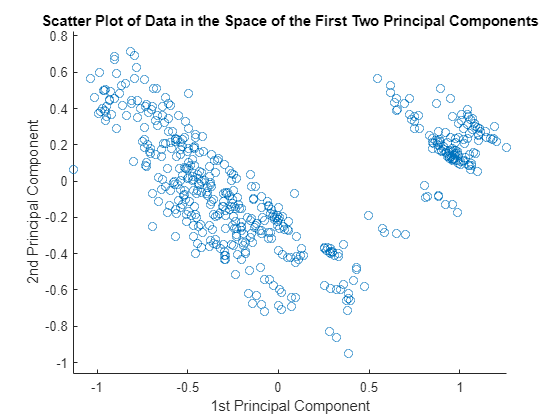

% Performing normalization of data in range [0,1]
X_standardized = normalize(X, "range");

[coeff, score, latent] = pca(X_standardized);

num_components = 12;

% Keep only the selected principal components
X_pca = score(:, 1:num_components);

% Split the data into training and testing sets

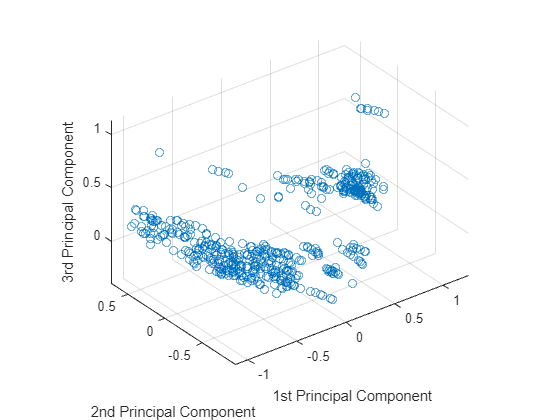

rng(10); 
cv = cvpartition(size(X_pca, 1), 'HoldOut', 0.2); % 80% train, 20% test
X_train = X_pca(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X_pca(test(cv), :);
Y_test = Y(test(cv), :);



% Define the architecture of the neural network
features = size(X_train, 2);

% 2 fully connected layers with relu activation
layers_NN_1 = [
    featureInputLayer(features)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer
];

% ADAM optimizer
options_NN_adam_1 = trainingOptions('adam', ... 
    'MaxEpochs', 100, ... 
    'MiniBatchSize', 32, ... 
    'InitialLearnRate', 0.01, ... 
    'Shuffle', 'every-epoch', ... 
    'ValidationData', {X_test, Y_test}, ... 
    'ValidationFrequency', 10, ... 
    'Verbose', false, ...

Mean Squared Error (MSE): 19.7015


    'Plots', 'training-progress');

net_NN_adam_1_pca = trainNetwork(X_train, Y_train, layers_NN_1, options_NN_adam_1);

% Make predictions on the validation data:
Y_pred_NN_pca = predict(net_NN_adam_1_pca, X_test);
Y_pred_NN_pca = double(Y_pred_NN_pca);

mse_NN_pca = immse(Y_test, Y_pred_NN_pca);
fprintf('Mean Squared Error (MSE) on test data: %.4f\n', mse_NN_pca);

NN comparsion table:

It looks like in case of neural network, PCA had a similar impact - we see an increase in MSE as we use less principle components. Overall, this kind of results might stem from the dataset shortcomings such as its small size. 

# **Categorical variables**

One of the limitations for any dataset when it comes to regression is how to deal with variables that are not numerical. This sections aims to give an example on what kind of transformation can be performed in order to standardize data for the regression task.

Overall, based on the reviewed literature [8, 9], the following are the most used methods on conveting categorical variables into another format, suitable to be considered with other numerical variables for regression model:

- One-Hot Encoding

- Ordinal Encoding

- Frequency Encoding

- Target Encoding

- Embedding

In this chapter, the investigation focuses on how the categorical features can be encoded using one-hot encoding in Matlab. For this purpose, a different dataset is used. It is downloaded from the ongoing competition on Kaggle dedicated to "Advanced regression techniques": [https://www.kaggle.com/competitions/house-prices-advanced-regression-techniques](https://www.kaggle.com/competitions/house-prices-advanced-regression-techniques)

% reading the data from the .csv file
newDataset = readtable('house-prices-advanced-regression-techniques\train.csv', VariableNamingRule = 'preserve'); 

More information on the dataset itself can be found following the above-mentioned link or in the "data_description.txt" file.

To make this experiment simpler, we shall focus only on one of the data columns - specifically, the feature that defines the building type. 

From the code below we can see what are possible values this variable can take, and the respective occurance in the training set.

columnName = 'BldgType';  
columnData = newDataset.(columnName);
[uniqueValues, ~, index] = unique(columnData);
occurrences = accumarray(index, 1);
uniqueData = table(uniqueValues, occurrences, 'VariableNames', {'UniqueValues', 'Occurrences'});
disp(uniqueData);

Now, let's perform one-hot encoding.

% Convert string values to categorical data type
columnData_categorical = categorical(columnData);

% Perform one-hot encoding
onehot_encoded = onehotencode(columnData_categorical,2);

% Convert the one-hot encoded data to a string format
encodedDataStrings = cell(size(onehot_encoded, 1), 1);

Mean Squared Error (MSE) after PCA: 19.0502


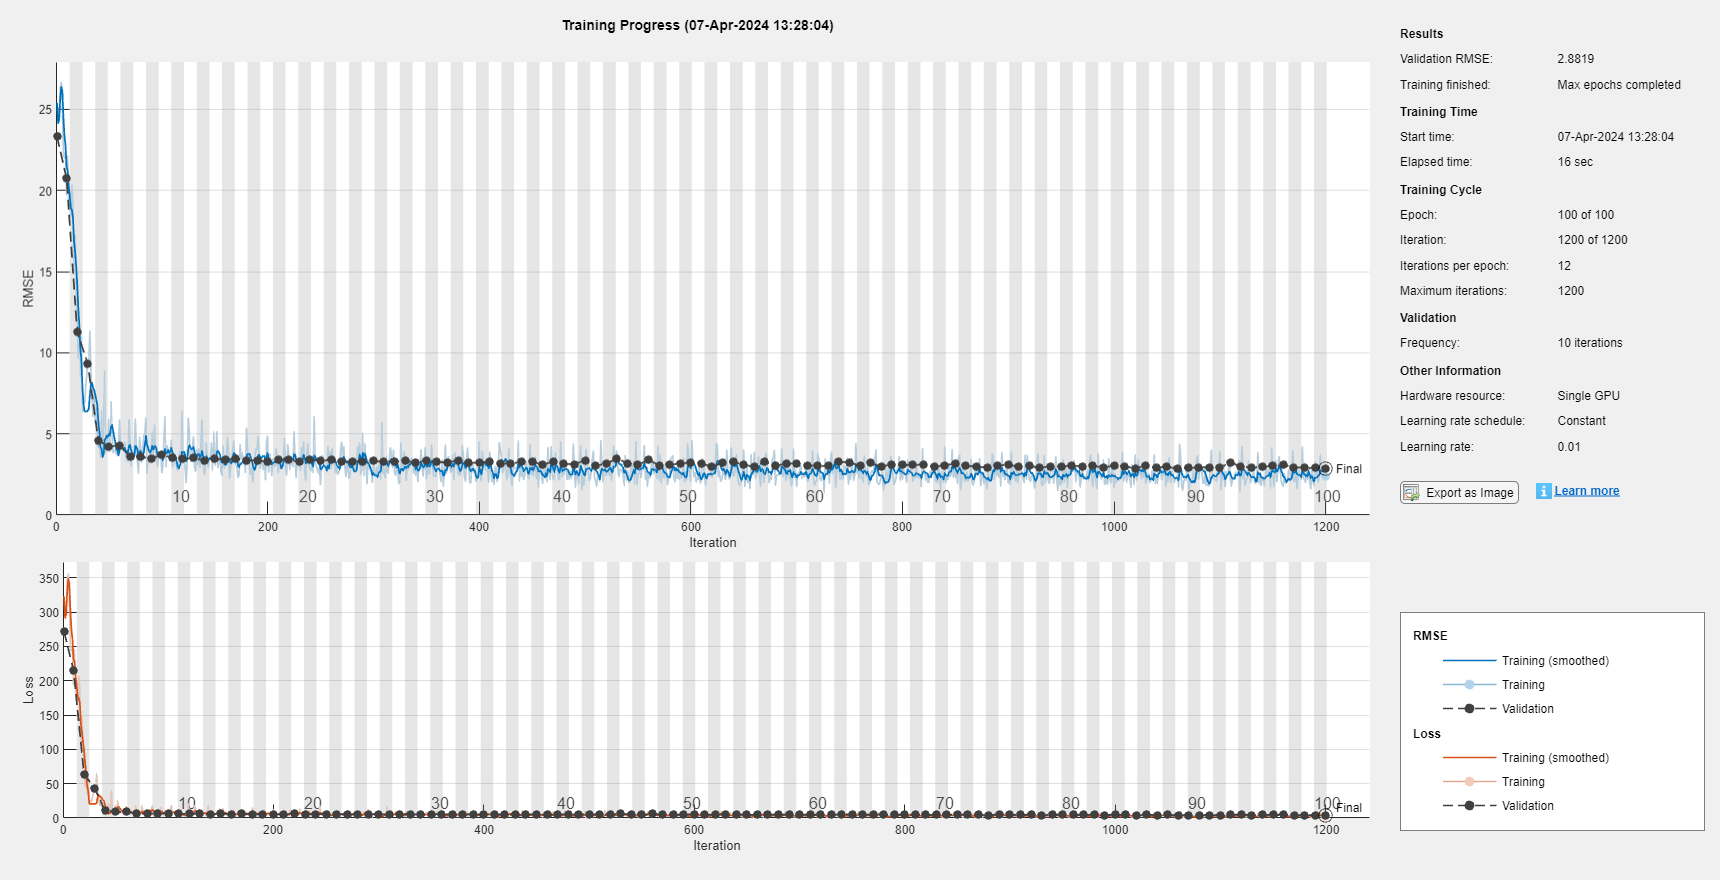

Mean Squared Error (MSE) on test data: 8.3056


    UniqueValues    Occurrences
    ____________    ___________

     {'1Fam'  }        1220    
     {'2fmCon'}          31    
     {'Duplex'}          52    
     {'Twnhs' }          43    
     {'TwnhsE'}         114    



      UniqueValues       Occurrences
    _________________    ___________

    {'0  0  0  0  1'}        114    
    {'0  0  0  1  0'}         43    
    {'0  0  1  0  0'}         52    
    {'0  1  0  0  0'}         31    
    {'1  0  0  0  0'}       1220    



for i = 1:size(onehot_encoded, 1)
    encodedDataStrings{i} = num2str(onehot_encoded(i, :));
end

% Check for unique values & their occurances
[uniqueValues, ~, index] = unique(encodedDataStrings);
occurrences = accumarray(index, 1);
uniqueData = table(uniqueValues, occurrences, 'VariableNames', {'UniqueValues', 'Occurrences'});

% Display the unique combinations and their occurrences
disp(uniqueData);

So, from displayed outputs we can see both the original categorical variables as well as their respective one-hot encodings. The count of occurances confirms the accuracy of conversion.

# **Analysis**

Multiple regression models were tested throughout this project. As the testing releaved most of the models managed to achieve reasonable results (1D CNN would be an exeption in this case). Particularly notable is the impact of normalizing the data, especially when it comes to neural networks and support vector machine with rbf kernel. 

Random Forest regression model showed the best performance with MSE of around 7. LSBoost model had a similar performance. This tells us that bootstrapping and boosting algorithms are very effective when it comes to regression. Meanwhile, for comparison, neural networks' best performance was slightly over mse = 11.

A few other methods were investigated, such as K-Nearest Neighbor. K-NN is more often used for classification problems, however, it may be utilized for regression as well. Based on the conducted testing, we saw that the model produced relatively high MSE score. Furthermore, judging based on the nature of the model, it would be very hard to get precise predictions since it is sensitive to outliers and noise in the data. Additionally, K-NN is a rather computationally heavy model - hence, it might become a problem on larger datasets.

Another aspect worth mentioning is models interpretability. Putting the MSE scores aside, it should be noted that linear models or decision trees are significantly easier to interpret and understand how the result was achieved, in comparsion to K-NN or Neural Networks.

Boston dataset shortcomings:

Some of the conducted experiments might not be giving us a full understanding of the models' abilities simply due to certain limitations that come from the used dataset.

As mentioned in previous sections, the dataset's size is pretty small (a little over 500 samples), and in fact it becomes one of the largest problems for machine learning models. Dataset of a small size leads to limited representation, limited generalization, might be more prone to overfitting, and simply difficult to validate. It is particularly challenging to do train-validation-test split on a dataset of such size - the models are then limited with the learning opportunities only from the data points that are available in the training dataset (which usually is somewhat between 70-80% from the original size). Furthermore, it becomes even more challenging when the dataset contains outliers. For example, Principle Component Analysis was explored in an attempt to improve models performances. However, it is the size of the dataset might be the reason for not gaining better performance. We should keep in mind that essentially PCA projects data into a low-dimentional subspace, leading to some loss of information. So when the dataset is small, this loss may be significant. 

Another issue specific to Boston dataset in the context of today is its actuality. The works in [10] and [11] discuss in detail issues, inaccuracies, and popularity of Boston dataset - that includes the formation of some of the features (such as *LSTAT*) as well as certain ethical considerations (for example, by adding the *B* feature, the authors suggest that racial self-segregation has impact on the house prices). All in all, nowadays the Boston dataset is nonethless used machine learning (although often from the principles learning perspective), but also for ethics-related studies. Multiple libraries often suggest using another dataset for building actual models, for example, scikit-learn recommends to use California dataset.

Keep in mind that this dataset was released in 1978, and it serves as a basis for learning & experimenting with machine learning & statistics. Given the knowledge acquired during this project, it would be advantageous to select a new dataset and employ various machine learning techniques to dive deeper into different models and their relevance in today's market prediction. 

Other datasets for consideration:

- Paris dataset: [https://www.kaggle.com/datasets/mssmartypants/paris-housing-price-prediction/data](https://www.kaggle.com/datasets/mssmartypants/paris-housing-price-prediction/data)

- California dataset: [https://www.kaggle.com/datasets/camnugent/california-housing-prices](https://www.kaggle.com/datasets/camnugent/california-housing-prices)

- House prices (Kaggle competition): [https://www.kaggle.com/competitions/house-prices-advanced-regression-techniques/data](https://www.kaggle.com/competitions/house-prices-advanced-regression-techniques/data)

# **Future works**

This project in Matlab can be seen as a foundational work for regression related tasks, and house price prediction in particular. 

One potential avenue for future enhancement involves identifying and addressing outliers within the dataset. While our initial exploration encompassed handling missing values, visualizing correlation matrices, and analyzing data distributions, we have yet to examine outliers. It's noteworthy that the Boston dataset, based on available information online, does contain outliers, which could contribute to higher Mean Squared Error (MSE) in certain predictions, as seen in the "Actual vs Predicted values" graphs. However, addressing outliers in the Boston dataset poses its own challenge - doing so may lead to a reduction in dataset size (which is already relatively small).

Another avenue for improvement is to go deeper instead of broader. Throughout the project multiple regression models were tested. In future, it would make sense to pick 2-3 models and explore more in detail various training options and hyperparameters. Additionally, the impact of regularization techniques, for example for neural networks, could be investigated - that might be particularly helpful for experiments with different, larger datasets.

One of the interesting ideas that was discovered as part of additional literature search later in the project is the use of 2D CNN for tabular data. In case of Boston dataset (and other similar kind of datasets), it is summarized in the format of a table. An interesting study on 2D CNN application for tabular data classification was presented in [12]. Perhaps, some similar implementation could be adapted in the context of a regression task.

Finally, another exciting area of research for the future developments is feature engineering. This process involves selecting, transforming, and creating new features from raw data to improve a model's ability to capture patterns and relationships within the data. Potentially, it may significantly impact the predictive power of a model, leading to better accuracy, generalization, and interpretability. 

# **References**

[1] S. Sanyal, S. Kumar Biswas, D. Das, M. Chakraborty and B. Purkayastha, "Boston House Price Prediction Using Regression Models," *2022 2nd International Conference on Intelligent Technologies (CONIT)*, Hubli, India, 2022, pp. 1-6, doi: 10.1109/CONIT55038.2022.9848309.

[2] Mohd, T., Jamil, N.S., Johari, N., Abdullah, L., Masrom, S. (2020). An Overview of Real Estate Modelling Techniques for House Price Prediction. In: Kaur, N., Ahmad, M. (eds) Charting a Sustainable Future of ASEAN in Business and Social Sciences. Springer, Singapore. 

[3] “Normalize data - MATLAB normalize,” *www.mathworks.com*. [https://www.mathworks.com/help/matlab/ref/double.normalize.html](https://www.mathworks.com/help/matlab/ref/double.normalize.html)

[4] “Ensemble Algorithms - MATLAB & Simulink,” *www.mathworks.com*. [https://www.mathworks.com/help/stats/ensemble-algorithms.html](https://www.mathworks.com/help/stats/ensemble-algorithms.html)

[5] “Support Vector Machine Regression - MATLAB & Simulink,” *www.mathworks.com*. [https://www.mathworks.com/help/stats/support-vector-machine-regression.html](https://www.mathworks.com/help/stats/support-vector-machine-regression.html)‌

[6] T. Srivastava, “Introduction to KNN, K-Nearest Neighbors : Simplified,” *Analytics Vidhya*, Mar. 07, 2019. [https://www.analyticsvidhya.com/blog/2018/03/introduction-k-neighbours-algorithm-clustering/](https://www.analyticsvidhya.com/blog/2018/03/introduction-k-neighbours-algorithm-clustering/)

[7] “PCA: Practical Guide to Principal Component Analysis in R & Python,” *Analytics Vidhya*, Mar. 21, 2016. [https://www.analyticsvidhya.com/blog/2016/03/pca-practical-guide-principal-component-analysis-python/](https://www.analyticsvidhya.com/blog/2016/03/pca-practical-guide-principal-component-analysis-python/)

[8] S. Gnat, “Impact of Categorical Variables Encoding on Property Mass Valuation,” *Procedia Computer Science*, vol. 192, pp. 3542–3550, 2021, doi: [https://doi.org/10.1016/j.procs.2021.09.127](https://doi.org/10.1016/j.procs.2021.09.127)‌

[9] M. K. Dahouda and I. Joe, “A Deep-Learned Embedding Technique for Categorical Features Encoding,” *IEEE Access*, vol. 9, pp. 114381–114391, 2021, doi: [https://doi.org/10.1109/ACCESS.2021.3104357](https://doi.org/10.1109/ACCESS.2021.3104357)

[10] M. Cantaro, “Things You Didn’t Know About the Boston Housing Dataset,” *Medium*, Jan. 19, 2020. [https://towardsdatascience.com/things-you-didnt-know-about-the-boston-housing-dataset-2e87a6f960e8](https://towardsdatascience.com/things-you-didnt-know-about-the-boston-housing-dataset-2e87a6f960e8)

[11] “Revisiting the Boston Housing Dataset — Fairlearn 0.9.0.dev0 documentation,” *fairlearn.org*. [https://fairlearn.org/main/user_guide/datasets/boston_housing_data.html](https://fairlearn.org/main/user_guide/datasets/boston_housing_data.html)

[12] L. Buturović, D. Miljković. "A novel method for classification of tabular data using convolutional neural networks." *BioRxiv* (2020): 2020-05.

‌